# MPS-Tensor to Quantum Gate

Author: Richard Milbradt

This is a demonstration of the method discussed in the thesis. We want to take the 4-tensors $N$ making up the solvable MPSs and turn them into unitary gates, that may be used to define gates in a quantum circuit. We will do this for the example of virtual and physical dimenson $\chi =d=2$, for which a complete parametrisation is given in [[Piroli2020](https://link.aps.org/doi/10.1103/PhysRevB.101.094304)]. We can create a random 4-tensor $N$:

% Random Parameters
K = 2*pi*rand(1,3);
u = randSU2;
v = randSU2;

% Using Parameters to create N leg-order: leftbond - phys1 - phys2 -
% rightbond
N = solvMPS(K,u,v)

N = N(:,:,1,1) =

   0.4582 - 0.2999i   0.0978 - 0.1006i
   0.1850 + 0.0965i   0.2363 + 0.2848i


N(:,:,2,1) =

  -0.0818 + 0.1405i   0.5304 - 0.2689i
  -0.1551 - 0.2565i   0.1650 + 0.0534i


N(:,:,1,2) =

   0.1592 - 0.0914i  -0.1821 + 0.2316i
  -0.4934 - 0.3264i   0.1042 + 0.1365i


N(:,:,2,2) =

   0.2014 - 0.3154i   0.1915 - 0.0565i
  -0.0789 - 0.1019i  -0.4921 - 0.2477i


Let us check, if $N$fulfils the desired property:

                                                                                        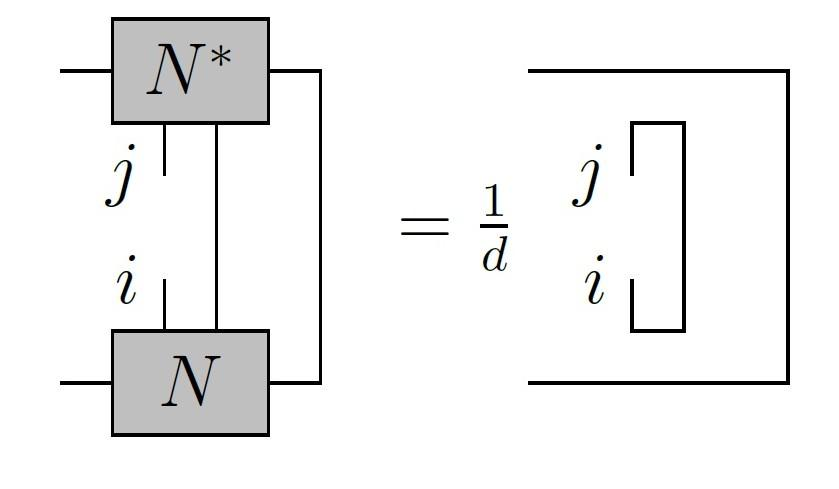

Nr = contract(N,4,[3,4],conj(N),4,[3,4]);

Nr = reshape(Nr,[4,4]);
maxerr = max(Nr-(1/2)*eye(4),[],'all') % Deviation is of the same magnitude as the numerical accuracy

maxerr = -1.1102e-16

So this works nicely. Next we want to make a unitary gate **ng **based on $N$. This is done by the function `unitarisation`. The details and reasoning can be found in the thesis in section 8.2.

                                                                                                        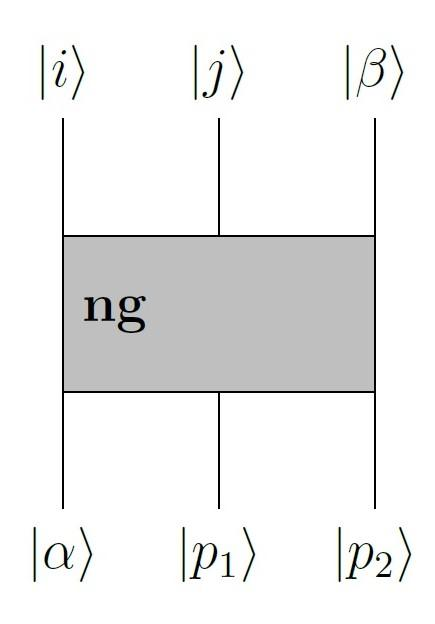

ng = unitarisation(N)

ng =    0.4582 - 0.2999i   0.1922 + 0.0565i  -0.2712 - 0.2127i  -0.2117 - 0.0191i   0.1850 + 0.0965i   0.2118 + 0.1504i  -0.6159 - 0.0404i  -0.0549 + 0.0324i
   0.1592 - 0.0914i  -0.2069 + 0.1842i  -0.1925 + 0.0098i   0.2909 - 0.1651i  -0.4934 - 0.3264i   0.2150 - 0.0465i   0.0171 + 0.0213i  -0.5837 + 0.0259i
  -0.0818 + 0.1405i   0.9262 - 0.0005i   0.0151 - 0.0262i   0.0804 + 0.0104i  -0.1551 - 0.2565i   0.0028 + 0.0268i   0.0587 - 0.0334i  -0.0712 - 0.0900i
   0.2014 - 0.3154i   0.0157 - 0.0160i   0.8992 + 0.0084i  -0.0051 + 0.0304i  -0.0789 - 0.1019i   0.0833 - 0.0104i  -0.1068 + 0.1074i  -0.0581 - 0.0034i
   0.0978 - 0.1006i   0.0865 - 0.0033i  -0.0020 + 0.0165i   0.9012 - 0.0080i   0.2363 + 0.2848i  -0.0163 - 0.0175i  -0.0657 + 0.0154i   0.1020 + 0.0892i
  -0.1821 + 0.2316i  -0.0000 + 0.0100i   0.0861 + 0.0041i  -0.0101 - 0.0248i   0.1042 + 0.1365i   0.9254 - 0.0008i   0.0886 - 0.0783i   0.0680 + 0.0209i
   0.5304 - 0.2689i   0.0953 - 0.0065i  -0.1179 - 0.0532i  -0.1036 + 0.0212i 

Let us check, if this gate does what we want.

**Unitarity:**

E = ng*ng'-eye(8);
maxerr = max(max(E)) % Deviation is of the same magnitude as the numerical accuracy

maxerr = -3.3307e-16

**Solvability Property:**

N1 = reshape(ng,[2,2,2,2,2,2]);
N1 = permute(N1,[3,2,1,6,5,4]); % Annoingly we work against the MATLAB convention.
N2 = N1(:,:,:,:,1,1);
NN = contract(N2,4,[2,3],conj(N2),4,[2,3]);
NN = reshape(NN,[4,4]);

maxerr = max(max(NN-(1/2)*eye(4))) % Deviation is of the same magnitude as the numerical accuracy

maxerr = -1.1102e-16

Thus the created **ng-**gate works as intended. It can now be used to do the actual implementation on a circuit based quantum computer.